**ecoSUB_process**

Script to process and plot science and engineerig data from ecoSUB instruments. 

Requires:

-     gsw toolbox [http://www.teos-10.org/software.htm](http://www.teos-10.org/software.htm)

-     cmocean [https://uk.mathworks.com/matlabcentral/fileexchange/57773-cmocean-perceptually-uniform-colormaps](https://uk.mathworks.com/matlabcentral/fileexchange/57773-cmocean-perceptually-uniform-colormaps)

*Lewis Drysdale, 2021, lewis.drysdale@sams.ac.uk*

clearvars; close('all')

Set filepaths and strings for incoming and outgoing data

- Set paths to data and figure folder

- Change testdate variable to reflect the folder in /logs

- Check the IMEI number to match the vehicle used

- Choose  quality control parameters to apply to the data

% 1. set paths to data and figure folder
indir       ='C:\ecoSUB C3 GUI\Logs';           % set file path 
figdir      = '\Users\SA01LD\Desktop\ecoSUB-toolbox\figures\'; % set outpath for figures
% 2. change testdate
testdate    ='20210811';                        % enter test date

% 3. check IMEI
imei        ='300434062118160' ;                % unique to each instrument

infolder    =fullfile(indir,testdate,imei);     % build file path
state_file  = dir([infolder filesep '*_ecosub_state_v2.csv']); % list relevant files
cstate_file = dir([infolder filesep '*_current_state.csv']); % list relevant files

% 4. choose some quality control parameters
lat_lim     = [56.4 56.5];  % geographical exclusion
lon_lim     = [-5.5 -5.3];  % geographical exclusion
dep_lim     = -0.5;          % depth exclusion

for kk = 1:numel(state_file)
    % read state v2
    statev2=readtable([infolder filesep state_file(kk).name],"PreserveVariableNames",false);
    % read current state
    cstate=readtable([infolder filesep cstate_file(kk).name],"PreserveVariableNames",false);

Extract data, apply QA to science data, and conversion to TEOS-10

    % extract science units
    D       =statev2.Depth;    
    C       =statev2.Conductivity;
    T       =statev2.Temperature;
    Lat     =statev2.Latitude;
    Lon     =statev2.Longitude;
    Lat_raw =statev2.Latitude;
    Lon_raw =statev2.Longitude;
    dr      =statev2.PositionEstimation;
    
    % apply quality control filters
    q1      = D<=dep_lim;
    q2      =Lat>=lat_lim(2) | Lat<=lat_lim(1);
    q3      =Lon>=lon_lim(2) | Lon<=lon_lim(1);
    ix      = q1 | q2 | q3;

    D(ix)=NaN;
    C(ix)=NaN;
    T(ix)=NaN;
    Lat(ix)=NaN;
    Lon(ix)=NaN;
    
    % calculate salinity and TEOS-10 salinity, temperature, density
    SP              = gsw_SP_from_C(C,T,D);
    [SA, in_ocean]  = gsw_SA_from_SP(SP,D,Lon,Lat);
    CT              = gsw_CT_from_t(SA,T,D);
    rho             = gsw_rho(SA,CT,D);

    % extract engineering units
    Time    =statev2.Time;
    mtime   =datenum(datetime(Time, 'convertfrom','posixtime'));
    Speed   =statev2.ForwardSpeed;
    Heading =statev2.Heading;
    Pitch   =statev2.Pitch;
    Roll    =statev2.Roll;
    RPM     =statev2.RPM;
    B1volt  =statev2.Battery1Volt;
    B1crnt  =statev2.Battery1Current;
    Rangle  =statev2.RudderAngle;
    
    % extract geo reference
    dr_ind      =statev2.PositionEstimation;
    lat_raw     =statev2.Latitude;
    lon_raw     =statev2.Longitude;
    
    mission =char(statev2.MissionName(1));

Plot science data

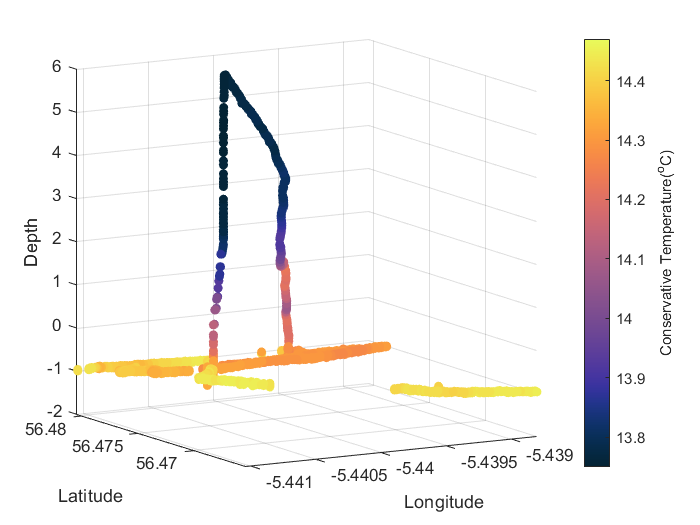

    fname=fullfile(figdir,[char(statev2.MissionName(1)) '-' datestr(mtime(1),30) '-temperature-3d']);
    
    ecoSUB_scatter(Lon,Lat,D,T,fname,'Conservative Temperature');

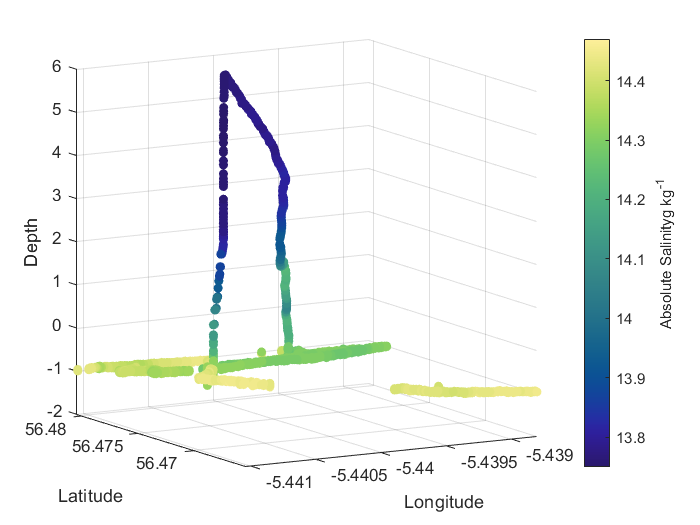

    
    fname=fullfile(figdir,[char(statev2.MissionName(1)) '-' datestr(mtime(1),30) '-salinity-3d']);
    
    ecoSUB_scatter(Lon,Lat,D,T,fname,'Absolute Salinity');

    
% if sum(~isnan(SP))>0
%     ecoSUB_plot_science
% end

Plot vehicle engineering units

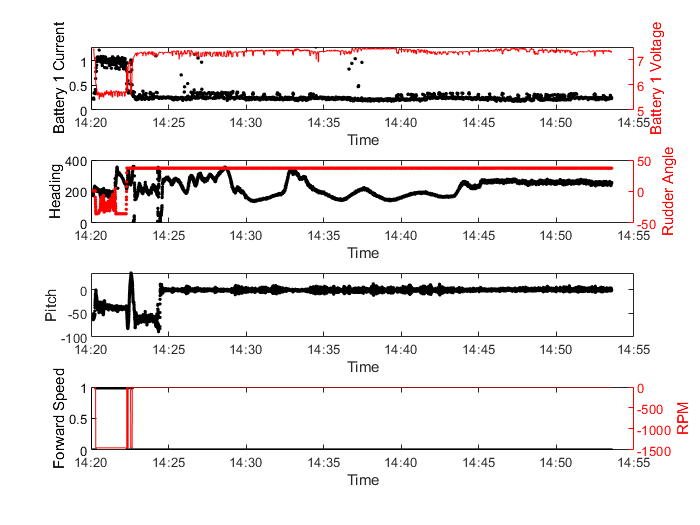

ecoSUB_plot_engineering

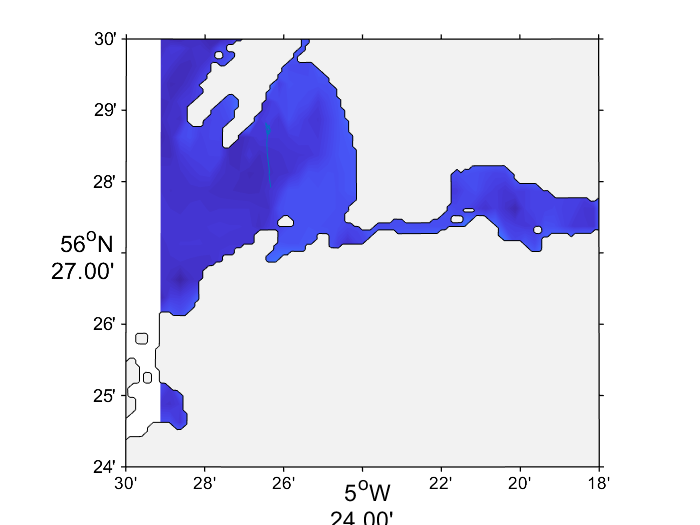

ecoSUB_plot_track

end